clear
clc
clf

## **(1)纯净语音与加扰语音样本之间的频谱差异**

纯净语音的幅频特性

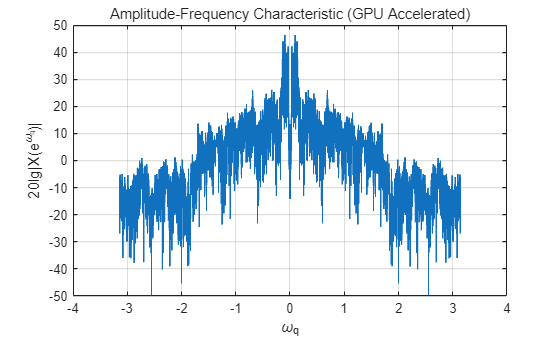

tic;
[x1,fs1] = audioread('trip.wav');
x1=mean(x1,2);
player_x1=audioplayer(x1,fs1);
draw_afc_gpu(x1);

toc;

历时 6.636135 秒。


加扰语音的幅频特性

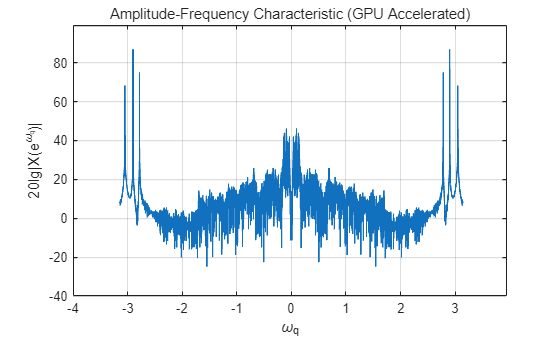

tic;
[x2,fs2] = audioread('6noise.wav');
x2=mean(x2,2);
player_x2=audioplayer(x2,fs2);
draw_afc_gpu(x2);

toc;

历时 2.333416 秒。


## **(2)**离散时间滤波器实现干扰抑制

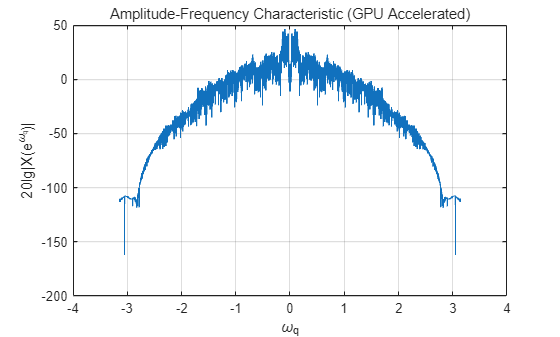

w1=2.78094;h1=[1,-2*cos(w1),1];
w2=2.90095;h2=[1,-2*cos(w2),1];
w3=3.04923;h3=[1,-2*cos(w3),1];
h=conv(h1,h2);h=conv(h,h3);
h=h/sum(h);
x2_fliter=conv(x2,h);
player_x2_fliter=audioplayer(x2_fliter,fs2);
tic;
draw_afc_gpu(x2_fliter);

toc;

历时 1.491058 秒。


## (3)内插与抽取处理

0阶保持内插+抽取

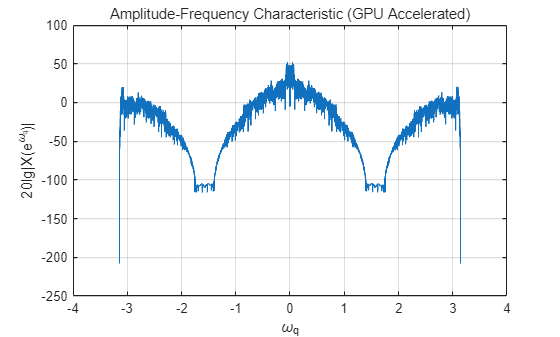

%0阶保持内插
x3=repelem(x2_fliter,2);
player_x3=audioplayer(x3,fs2*2);
tic;
draw_afc_gpu(x3);

toc;

历时 1.548210 秒。


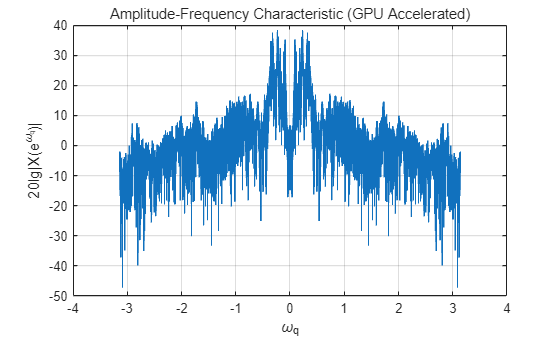

%抽取
x3_5=downsample(x3,5);
player_x3_5=audioplayer(x3_5,fs2*2/5);
tic;
draw_afc_gpu(x3_5);

toc;

历时 1.332822 秒。


时间截断的理想低通滤波器内插+抽取

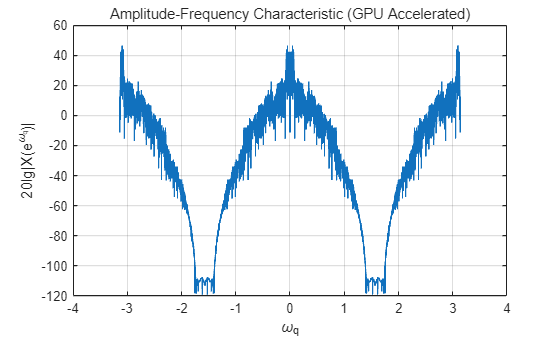

%时间截断的理想低通滤波器
%补0，增加采样率
x4=upsample(x2_fliter,2);
tic;
draw_afc_gpu(x4);

toc;

历时 1.727233 秒。


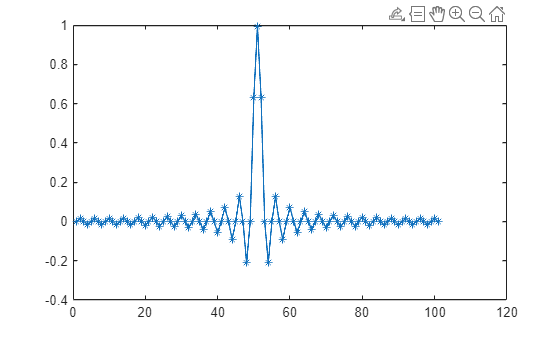

%设计低通滤波
h4_length=101;
h4=zeros(h4_length,1);
center = (h4_length + 1) / 2;

for i = 1:h4_length  
    t = i - center;
    if abs(t) < eps
        h4(i) = 0.5;  
    else
        h4(i) = sin((pi/2) * t) / (pi * t);  
    end
end
h4=h4/sum(h4);
h4=h4*2;
plot(h4,'*-');

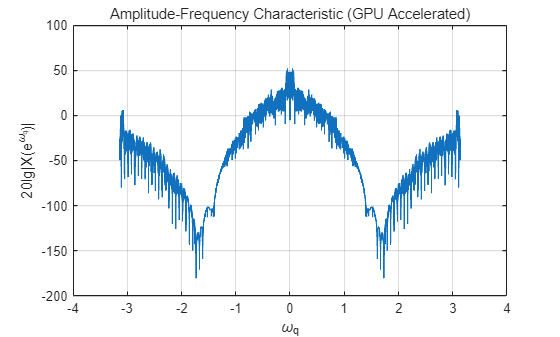

x4=conv(x4,h4);
player_x4=audioplayer(x4,fs2*2);
tic;
draw_afc_gpu(x4);

toc;

历时 1.558512 秒。


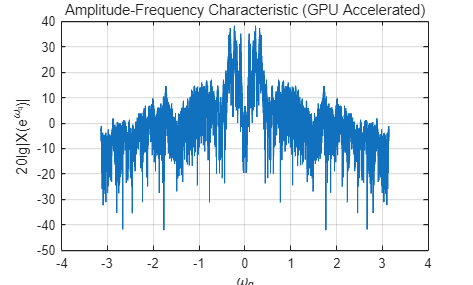

%抽取
x4_5=downsample(x4,5);
player_x4_5=audioplayer(x4_5,fs2*2/5);
tic;
draw_afc_gpu(x4_5);

toc;

历时 1.179981 秒。
